# Simulazione Filtri

### creazione variabili

#### Simboli

clear all;
syms R1 R2 C1 C2 omega f
assume(R1,{'positive','real'});
assume(R2,{'positive','real'});
assume(C1,{'positive','real'});
assume(C2,{'positive','real'});
assume(omega,{'positive','real'});
assume(f,{'positive','real'});
assumeAlso(R1 ~= 0);
assumeAlso(R2 ~= 0);
assumeAlso(C1 ~= 0);
assumeAlso(C2 ~= 0);
assumeAlso(omega ~= 0);
assumeAlso(f ~= 0);
syms omega_a omega_b
assume(omega_a,{'positive','real'});
assume(omega_b,{'positive','real'});
assumeAlso(omega_a ~= 0);
assumeAlso(omega_b ~= 0);
syms f_a f_b
assume(f_a,{'positive','real'});
assume(f_b,{'positive','real'});
assumeAlso(f_a ~= 0);
assumeAlso(f_b ~= 0);

#### Valori

R1_val = 100E+3;   % 100 kOhm
R2_val = 1E+3;     % 1kOhm
C1_val = 47E-9;    % 47nF
C2_val = 100E-9;   % 100nF
omega_a_val = 1 / (C1_val * R1_val);
omega_b_val = 1 / (C2_val * R2_val);
f_a_val = omega_a_val / (2 * pi);
f_b_val = omega_b_val / (2 * pi);

### Filtro passa-alto

è quello formato da C1 e R1:

[Vth_a, Rth_a] = calcola_thevenen(impedenza_condensatore(C1, omega), R1);

### Filtro passa-baso

[Vth_b, Rth_b] = calcola_thevenen(R2, impedenza_condensatore(C2, omega))

$$Vth\_b = \frac{1}{1+C_{2}\,R_{2}\,\omega \,\mathrm{i}}$$

$$Rth\_b = \frac{1}{\frac{1}{R_{2}}+C_{2}\,\omega \,\mathrm{i}}$$

## CRRC

Metto che inizialmente il segnale ha valore unitario

Dopo il primo attenuatore, il segnale ha una tensione Vth con un impedenza di uscita Rth:

[Vth, Rth] = calcola_thevenen(impedenza_condensatore(C1, omega), R1)

$$Vth = -\frac{1}{-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }}$$

$$Rth = \frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}$$

il ramo a destra ha un'impedenza z2:

Z2 = impedenza_condensatore(C2, omega) + R2

$$Z2 = R_{2}-\frac{\mathrm{i}}{C_{2}\,\omega }$$

Allora su questo ramo ci scorre una corrente I2

I2 = Vth / (Rth + Z2)

$$I2 = -\frac{1}{\left(-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

allora la tensione in uscita è:

Vout = I2 * impedenza_condensatore(C2, omega)

$$Vout = \frac{\mathrm{i}}{C_{2}\,\omega \,\left(-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

Vout = simplify(subs(Vout, R2, 1 / (omega_b * C2)));
Vout = simplify(subs(Vout, R1, 1 / (omega_a * C1)));

Quidni in definitiva:

H_CRRC = Vout;

e sostituendo le omega con le frequenze:

H_CRRC = subs(H_CRRC, omega, f * 2 * pi);
H_CRRC = subs(H_CRRC, omega_a, f_a * 2 * pi);
H_CRRC = subs(H_CRRC, omega_b, f_b * 2 * pi);
H_CRRC = simplify(H_CRRC)

$$H\_CRRC = \frac{C_{1}\,f\,f_{b}\,\mathrm{i}}{C_{1}\,f_{a}\,f_{b}-C_{1}\,f^{2}+C_{1}\,f\,f_{a}\,\mathrm{i}+C_{1}\,f\,f_{b}\,\mathrm{i}+C_{2}\,f\,f_{b}\,\mathrm{i}}$$

guadagno e sfasamento risultano:

A = sqrt((conj(H_CRRC) * H_CRRC));
A = simplify(A)

$$A = \frac{C_{1}\,f\,f_{b}}{\sqrt{{C_{1}}^{2}\,f^{4}+{C_{1}}^{2}\,f^{2}\,{f_{a}}^{2}+{C_{1}}^{2}\,f^{2}\,{f_{b}}^{2}+{C_{1}}^{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+2\,C_{1}\,C_{2}\,f^{2}\,f_{a}\,f_{b}+2\,C_{1}\,C_{2}\,f^{2}\,{f_{b}}^{2}+{C_{2}}^{2}\,f^{2}\,{f_{b}}^{2}}}$$

tanTheta = simplify(imag(H_CRRC) / real(H_CRRC))

$$tanTheta = \frac{C_{1}\,\left(f_{a}\,f_{b}-f^{2}\right)}{f\,\left(C_{1}\,f_{a}+C_{1}\,f_{b}+C_{2}\,f_{b}\right)}$$

Il guadagno sostituendo i numeri è dunque:

tmp = H_CRRC;
tmp = subs(tmp, C1, C1_val);
tmp = subs(tmp, C2, C2_val);
tmp = subs(tmp, R1, R1_val);
tmp = subs(tmp, R2, R2_val);
tmp = subs(tmp, f_a, f_a_val);
tmp = subs(tmp, f_b, f_b_val);
tmp = simplify(tmp);

guadagno_val = simplify(sqrt((conj(tmp) * tmp)));
sfasamento_val = simplify(atan(imag(tmp) / real(tmp)));

### Plot

Prima troviamo l'espressione con i nostri parametri:

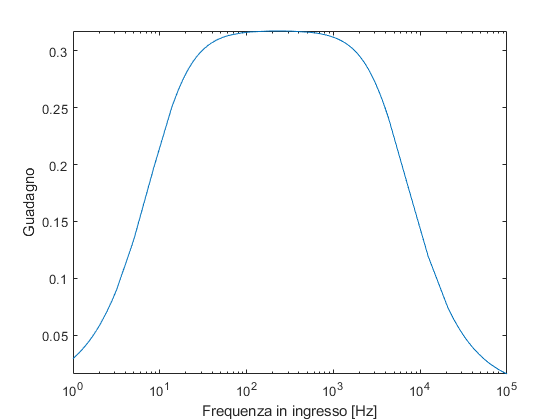

% figure;
% p1 = subplot(3,1,[1, 2]);
% fplot(guadagno_val, [1 100000]);
% set(gca, 'XScale', 'log');
% ylabel("guadagno A_{CRRC}");
% p2 = subplot(3,1,3)
% ylabel("sfasamento [Rad]");
% xlabel("frequenza in ingresso [Hz]");
% fplot(sfasamento_val, [1 100000])
fplot(guadagno_val, [1 100000])
set(gca, 'XScale', 'log')
ylabel("Guadagno")
xlabel("Frequenza in ingresso [Hz]")

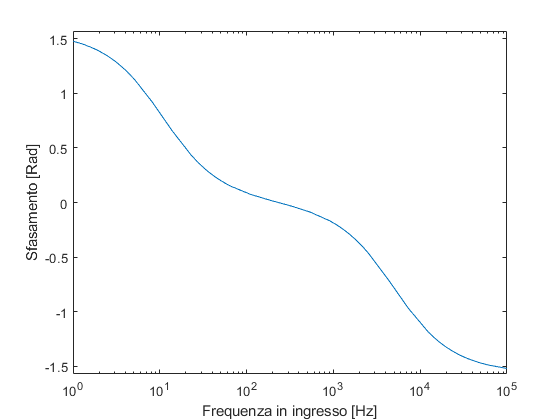


fplot(sfasamento_val, [1 100000])
set(gca, 'XScale', 'log')
set(gca, 'YLim', [-pi/2, pi/2])
ylabel("Sfasamento [Rad]")
xlabel("Frequenza in ingresso [Hz]")

### derivate

A_1 = diff(A, f);
f_max = solve(A_1, f)

$$f\_max = \sqrt{f_{a}}\,\sqrt{f_{b}}$$

A_max = subs(A, f, f_max)

$$A\_max = \frac{C_{1}\,\sqrt{f_{a}}\,{f_{b}}^{3/2}}{\sqrt{{C_{1}}^{2}\,{f_{a}}^{3}\,f_{b}+2\,{C_{1}}^{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+{C_{1}}^{2}\,f_{a}\,{f_{b}}^{3}+2\,C_{1}\,C_{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+2\,C_{1}\,C_{2}\,f_{a}\,{f_{b}}^{3}+{C_{2}}^{2}\,f_{a}\,{f_{b}}^{3}}}$$

### Equivalente Thevenen

Vth = A

$$Vth = \frac{C_{1}\,f\,f_{b}}{\sqrt{{C_{1}}^{2}\,f^{4}+{C_{1}}^{2}\,f^{2}\,{f_{a}}^{2}+{C_{1}}^{2}\,f^{2}\,{f_{b}}^{2}+{C_{1}}^{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+2\,C_{1}\,C_{2}\,f^{2}\,f_{a}\,f_{b}+2\,C_{1}\,C_{2}\,f^{2}\,{f_{b}}^{2}+{C_{2}}^{2}\,f^{2}\,{f_{b}}^{2}}}$$

Rth1 = Rth

$$Rth1 = \frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}$$

[~, Rth] = calcola_thevenen(impedenza_condensatore(C2, omega), R2 + Rth1)

$$Rth = \frac{1}{C_{2}\,\omega \,\mathrm{i}+\frac{1}{R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}}}$$

Rth = simplify(Rth)

$$Rth = \frac{1}{C_{2}\,\omega \,\mathrm{i}-\frac{C_{1}\,R_{1}\,\omega -\mathrm{i}}{-C_{1}\,R_{1}\,R_{2}\,\omega +R_{1}\,\mathrm{i}+R_{2}\,\mathrm{i}}}$$

Rth = simplify(subs(Rth, C1, 1 / (omega_a * R1)));
Rth = simplify(subs(Rth, C2, 1 / (omega_b * R2)));
Rth = subs(Rth, omega_a, f_a * 2 * pi);
Rth = subs(Rth, omega_b, f_b * 2 * pi);
Rth = subs(Rth, omega, f * 2 * pi);
Rth = simplify(Rth)

$$Rth = -\frac{R_{2}\,f_{b}\,\left(-R_{2}\,f+R_{1}\,f_{a}\,\mathrm{i}+R_{2}\,f_{a}\,\mathrm{i}\right)}{R_{2}\,f^{2}\,\mathrm{i}+R_{1}\,f\,f_{a}+R_{2}\,f\,f_{a}+R_{2}\,f\,f_{b}-R_{2}\,f_{a}\,f_{b}\,\mathrm{i}}$$


Rth = subs(Rth, C1, C1_val);
Rth = subs(Rth, C2, C2_val);
Rth = subs(Rth, R1, R1_val);
Rth = subs(Rth, R2, R2_val);
Rth = subs(Rth, f_a, f_a_val);
Rth = subs(Rth, f_b, f_b_val);
Rth = subs(Rth, omega_a, omega_a_val);
Rth = subs(Rth, omega_b, omega_b_val);
Rth = simplify(Rth)

$$Rth = \frac{246280345629554235763977093120\,\left(1000\,f-\frac{60167706435078180875}{17592186044416}\,\mathrm{i}\right)}{154742504910672534362390528\,f^{2}\,\mathrm{i}+775521088365404801521514708992\,f-8339730721983833947619531071755\,\mathrm{i}}$$

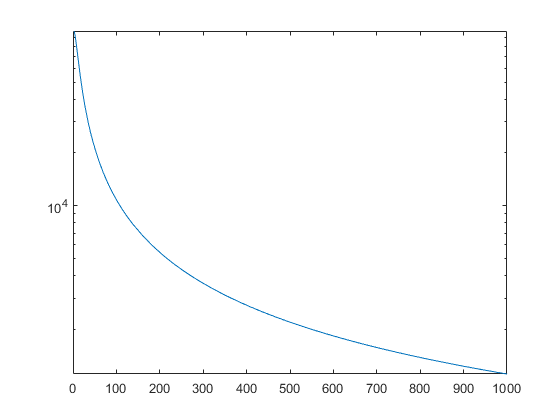

fplot(abs(Rth), [1, 1000])
set(gca, 'YScale', 'log')

## RCCR

La prima parte è come prima, ma sono scambiati i componenti

[Vth, Rth] = calcola_thevenen(R2, impedenza_condensatore(C2, omega));
Z2 = impedenza_condensatore(C1, omega) + R1;
I2 = Vth / (Rth + Z2);
Vout = I2 * R1

$$Vout = \frac{R_{1}}{\left(1+C_{2}\,R_{2}\,\omega \,\mathrm{i}\right)\,\left(R_{1}+\frac{1}{\frac{1}{R_{2}}+C_{2}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{1}\,\omega }\right)}$$


Vout = simplify(subs(Vout, R2, 1 / (omega_b * C2)));
Vout = simplify(subs(Vout, R1, 1 / (omega_a * C1)));
H_RCCR = Vout;

H_RCCR = subs(H_RCCR, omega, f * 2 * pi);
H_RCCR = subs(H_RCCR, omega_a, f_a * 2 * pi);
H_RCCR = subs(H_RCCR, omega_b, f_b * 2 * pi);
H_RCCR = simplify(H_RCCR)

$$H\_RCCR = -\frac{C_{2}\,f\,f_{b}\,\left(f-f_{b}\,\mathrm{i}\right)}{\left(f_{b}+f\,\mathrm{i}\right)\,\left(C_{2}\,f_{a}\,f_{b}-C_{2}\,f^{2}+C_{1}\,f\,f_{a}\,\mathrm{i}+C_{2}\,f\,f_{a}\,\mathrm{i}+C_{2}\,f\,f_{b}\,\mathrm{i}\right)}$$


A = sqrt((conj(H_RCCR) * H_RCCR));
A = simplify(A)

$$A = \frac{C_{2}\,f\,f_{b}}{\sqrt{{C_{1}}^{2}\,f^{2}\,{f_{a}}^{2}+2\,C_{1}\,C_{2}\,f^{2}\,{f_{a}}^{2}+2\,C_{1}\,C_{2}\,f^{2}\,f_{a}\,f_{b}+{C_{2}}^{2}\,f^{4}+{C_{2}}^{2}\,f^{2}\,{f_{a}}^{2}+{C_{2}}^{2}\,f^{2}\,{f_{b}}^{2}+{C_{2}}^{2}\,{f_{a}}^{2}\,{f_{b}}^{2}}}$$

tanTheta = simplify(imag(H_RCCR) / real(H_RCCR))

$$tanTheta = \frac{C_{2}\,\left(f_{a}\,f_{b}-f^{2}\right)}{f\,\left(C_{1}\,f_{a}+C_{2}\,f_{a}+C_{2}\,f_{b}\right)}$$


tmp = H_RCCR;
tmp = subs(tmp, C1, C1_val);
tmp = subs(tmp, C2, C2_val);
tmp = subs(tmp, R1, R1_val);
tmp = subs(tmp, R2, R2_val);
tmp = subs(tmp, f_a, f_a_val);
tmp = subs(tmp, f_b, f_b_val);
tmp = simplify(tmp);

guadagno_val = simplify(sqrt((conj(tmp) * tmp)));
sfasamento_val = simplify(atan(imag(tmp) / real(tmp)));

### Plot

Prima troviamo l'espressione con i nostri parametri:

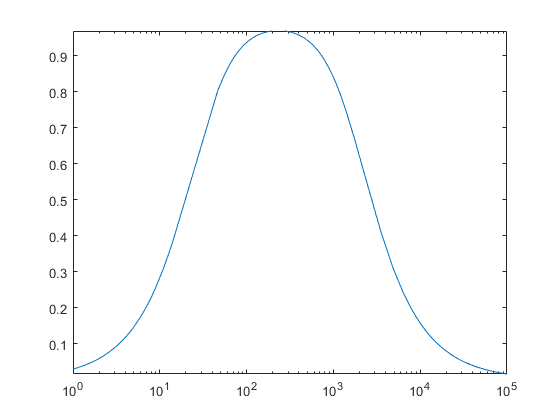


fplot(guadagno_val, [1 100000], "MeshDensity", 10)
set(gca, 'XScale', 'log')

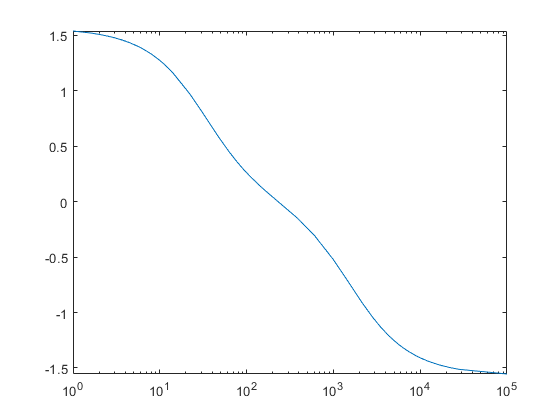

fplot(sfasamento_val, [1 100000], "MeshDensity", 10)
set(gca, 'XScale', 'log')

### derivate

A_1 = diff(A, f);
f_max = solve(A_1, f)

$$f\_max = \sqrt{f_{a}}\,\sqrt{f_{b}}$$

A_max = subs(A, f, f_max)

$$A\_max = \frac{C_{2}\,\sqrt{f_{a}}\,{f_{b}}^{3/2}}{\sqrt{{C_{1}}^{2}\,{f_{a}}^{3}\,f_{b}+2\,C_{1}\,C_{2}\,{f_{a}}^{3}\,f_{b}+2\,C_{1}\,C_{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+{C_{2}}^{2}\,{f_{a}}^{3}\,f_{b}+2\,{C_{2}}^{2}\,{f_{a}}^{2}\,{f_{b}}^{2}+{C_{2}}^{2}\,f_{a}\,{f_{b}}^{3}}}$$

#### Funzioni thevenen

function [ratio_Vth_Vin, Rth] = calcola_thevenen(r1, r2)
    ratio_Vth_Vin = 1 / (r1/r2 + 1);
    Rth = 1 / (1/r1 + 1/r2);
end
function [Z] = impedenza_condensatore(c, omega)
    Z = 1 / (j  * omega * c);
end